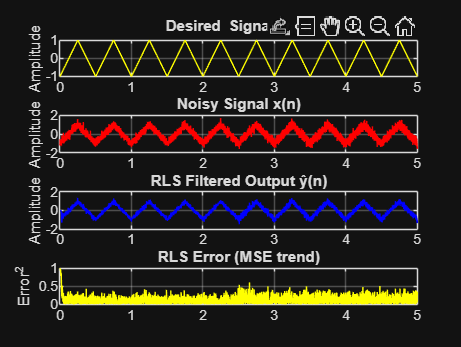

%% Parameters
N = 5000;                 
t = linspace(0,5,N)';    

% Desired signal (same as before)
s = sawtooth(2*pi*2*t(1:N,1), 0.5);   

% Noise (non-stationary + WGN)
phi = pi/6;
n1 = 0.2*sin(2*pi*50*t(1:N/2,1) - phi);
n2 = 0.3*sin(2*pi*100*t(N/2+1:N,1) - phi);
nwg = awgn(s, 10, 'measured') - s;
eta = [n1; n2];
noise = eta + nwg;

x = s + noise;
r_n = 0.3 * (nwg + sin(2*pi*50*t + pi/6) + sin(2*pi*100*t + pi/4));

%% RLS Adaptive Filter
M = 10;                  % Filter order
lambda = 0.99;           % Forgetting factor
delta = 0.01;            % Small constant
w = zeros(M,1);          % Initial weights
P = (1/delta)*eye(M);    % Initial inverse correlation matrix

y_hat_rls = zeros(N,1);  % Filter output
e_rls = zeros(N,1);      % Error

for n = M:N
    r = r_n(n:-1:n-M+1);   % Input vector
    k = (P*r) / (lambda + r'*P*r);   % Gain vector
    alpha = x(n) - w'*r;            % A priori error
    w = w + k*alpha;                 % Update weights
    P = (1/lambda)*(P - k*r'*P);     % Update P
    y_hat_rls(n) = w'*r;             % Output
    e_rls(n) = x(n) - y_hat_rls(n); % Error
end

%% Absolute error
abs_err = abs(s - e_rls);
%% Plots
figure;
subplot(4,1,1);
plot(t, s, 'y','LineWidth',0.2); grid on;
title('Desired Signal y_i(n)'); ylabel('Amplitude');

subplot(4,1,2);
plot(t, x, 'r'); grid on;
title('Noisy Signal x(n)'); ylabel('Amplitude');

subplot(4,1,3);
plot(t, e_rls, 'b','LineWidth',0.2); grid on;
title('RLS Filtered Output ŷ(n)'); ylabel('Amplitude');

subplot(4,1,4);
plot(t, abs_err,'y'); grid on;
title('RLS Error (MSE trend)'); ylabel('Error^2');


mse_rls = mean((s - e_rls).^2);
disp(['MSE (RLS) = ', num2str(mse_rls)]);

MSE (RLS) = 0.025377



lambda_values = [0.95, 0.99, 1];
M_values = [5, 10, 20];
mse_results = zeros(length(lambda_values), length(M_values));

for i = 1:length(lambda_values)
    for j = 1:length(M_values)
        lambda_val = lambda_values(i);
        M_val = M_values(j);
        w_val = zeros(M_val,1);
        y_hat_val = zeros(N,1);
        P = (1/delta)*eye(M_val);
        for n = M_val:N
            r = r_n(n:-1:n-M_val+1);   % Input vector
            k = (P*r) / (lambda_val + r'*P*r);   % Gain vector
            alpha = x(n) - w_val'*r;            % A priori error
            w_val = w_val + k*alpha;                 % Update weights
            P = (1/lambda_val)*(P - k*r'*P);     % Update P
            y_hat_val(n) = w_val'*r;             % Output
            e_rls(n) = x(n) - y_hat_val(n); % Error
        end
        mse_results(i,j) = mean((s - e_rls).^2);
    end
end

disp('MSE results (rows=lambda, cols=M):');

MSE results (rows=lambda, cols=M):


disp(mse_results);

    0.0383    0.0392    0.1434
    0.0345    0.0252    0.0381
    0.0472    0.0422    0.0420

